# Анализ статистических данных в MATLAB

Проанализируем данные выборки людей, полученные из соцсети VK

## Загрузка данных

Загружаем из файла `friends.mat` информацию о людях и их друзьях 

load friends

Чтобы получить свои данные воспользуйтесь скриптом `get_friends`:

В загруженных данных:

- `source` -  ID пользователя-источника, из друзей которого получен данный пользователь

- `id` - уникальный идентификатор (ID) пользователя

- `sex` - пол (1 - Ж, 2 - М)

- `birthday` - дата рождения

- `city` - город проживания

- `country` - страна проживания

- `status` - текстовый статус пользователя

## Фильтрация данных

(используются в т.ч. функции из *Statistics and Machine Learning Toolbox*)

Получим количество друзей для каждого пользователя-"источника"

C = groupsummary(data, 'source')

C = 168×2 table
    source    GroupCount
    ______    __________

       60        499    
      411        522    
      540        985    
     1165        230    
     1385        792    
     1676        260    
     1756        154    
     1856        230    
     2106        354    
     2444        332    
     2673        663    
     2996        282    
     3073        182    
     3083        265    
     3173        230    
     3333        694    


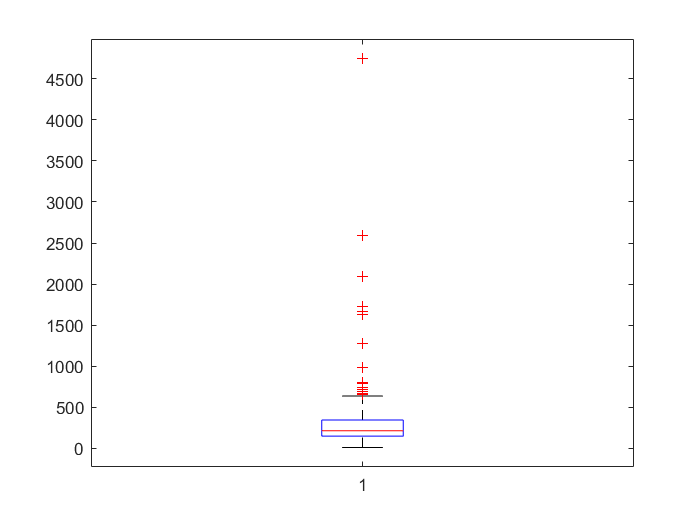

count = C.GroupCount;
boxplot(count);

Найдем верхнюю статистическую границу количества друзей

upper = iqr(count) * 1.5 + quantile(count, 0.75)

upper = 641.2500

Находим "источники", у которых количество друзей превышает границу (выбросы)

bad_sources = C.source(count > upper);

Удаляем из таблицы всех друзей этих "источников"

bad_rows = ismember(data.source, bad_sources);
data(bad_rows, :) = [];

Извлекаем из таблицы связи между пользователями

relations = data(:, {'source', 'id'});
data.source = [];

Удаляем повторяющиеся строки из таблицы

data = unique(data, 'rows');

Переведем данные о поле (`sex`) в массив категорий (`categorical`)

data.sex = categorical(data.sex, [1 2], ["Female", "Male"]);

Найдем пользователей, у которых не указан пол

no_sex = ismissing(data.sex);
nnz(no_sex)

ans = 4

Удалим из таблицы пользователей, у которых не указан пол

data = rmmissing(data, 'DataVariables', 'sex');

## Анализ и визуализация

### Анализ пола

Построим круговую диаграмму

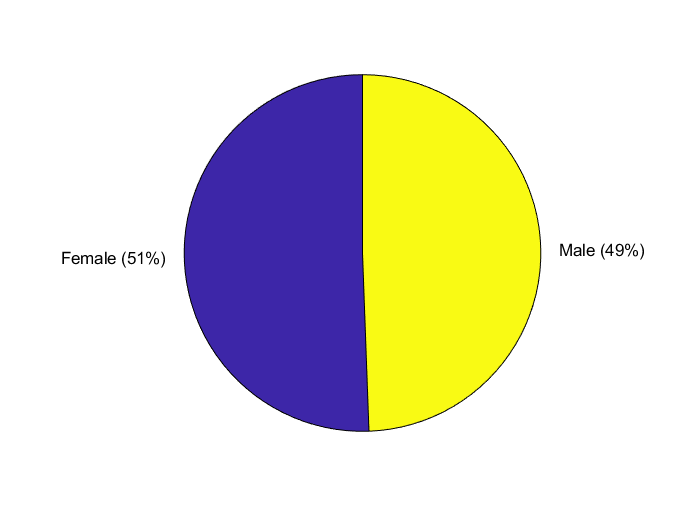

figure
pie(data.sex)

### Анализ возраста

Переведем дату рождения в формат `datetime`

data.birthday = datetime(data.birthday);

Запишем возраст каждого человека в новый столбец `age`

data.age = years(datetime('today') - data.birthday);

Найдем статистику по возрасту в зависимости от пола

age_stat = groupsummary(data, 'sex', {'min', 'max', 'median'}, 'age')

age_stat = 2×5 table
     sex      GroupCount    min_age    max_age    median_age
    ______    __________    _______    _______    __________

    Female      13262        13.93     116.82        28.31  
    Male        12959       13.889     116.85       29.079  


Классифицируем людей по возрасту (в соответствии с ВОЗ)

edges = [0 18 66 80 100 150]

edges =      0    18    66    80   100   150


cats = ["kid", "young", "middle", "senior", "old"]

cats = 1×5 string array
    "kid"    "young"    "middle"    "senior"    "old"


data.agecat = discretize(data.age, edges, 'categorical', cats)

data = 26221×9 table
    id    first_name      sex       birthday            city           country                                                                         status                                                                         age        agecat   
    __    ___________    ______    ___________    _________________    ________    ______________________________________________________________________________________________________________________________________________    ______    ___________

     5    'Данил'        Male      18-Oct-1986    'Санкт-Петербург'    'Россия'    '"Даже если вернусь изувеченным, в окровавленном треснутом шлеме, Всё равно свои планы 

Строим гистограмму по категориям

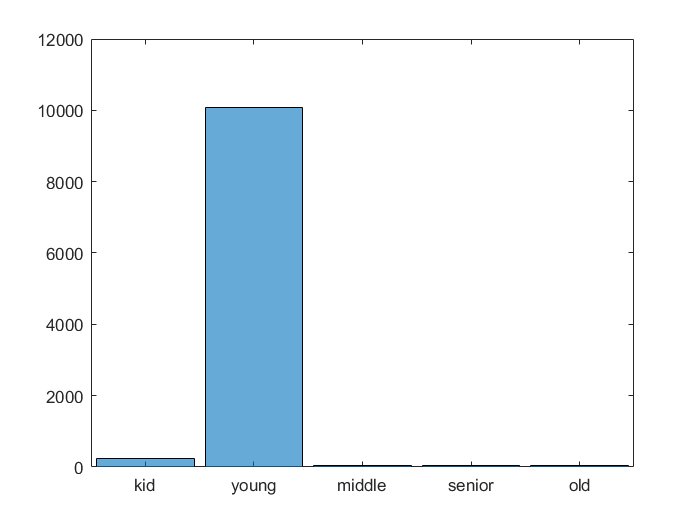

figure
histogram(data.agecat)

Вытащим из данных молодых людей (`young`)

young = data(data.agecat == "young", 'age');

Построим гистограмму возраста для молодых

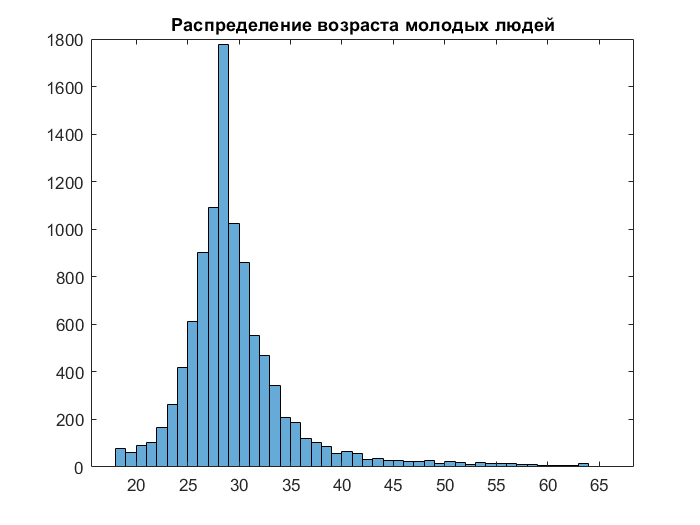

figure
histogram(young.age)
title("Распределение возраста молодых людей")

### Исследование связей

Подготовим данные для построения графа друзей

EdgeTable = mergevars(relations, {'id', 'source'}, 'NewVariableName', 'EndNodes')

EdgeTable = 35202×1 table
      EndNodes  
    ____________

      60    3073
     411    3073
     540    3073
    1165    3073
    1385    3073
    1676    3073
    1756    3073
    1856    3073
    2106    3073
    2444    3073
    2673    3073
    2996    3073
    3083    3073
    3173    3073
    3333    3073
    3382    3073


Создаем граф

G = graph(EdgeTable);

Упрощаем граф

G = simplify(G);
G = rmnode(G, find(degree(G) < 4));

Визуализируем граф

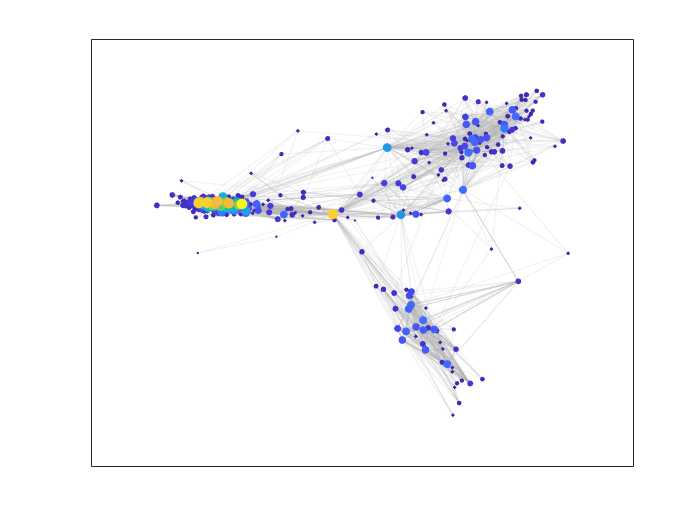

figure
g = plot(G, 'EdgeColor', [.7 .7 .7], 'EdgeAlpha', 0.2);
g.MarkerSize = log(degree(G)) + 0.1;
g.NodeCData = degree(G);

### Анализ местоположения

В таблице создадим новый столбец с местоположением пользователя

data = convertvars(data, {'city', 'country'}, 'string');
data = standardizeMissing(data, "", 'DataVariables', {'city', 'country'});
data.location = data.country + ", " + data.city;

Загружаем географичесие координаты (геокоды) пользователей

load geodata.mat

Если вы используете свои данные пользователей, необходимо получить для них свои геокоды:

Определим, сколько человек живет в каждой локации

C0 = groupsummary(data, 'location');

Объединим эти данные с таблицей геокодов

C = innerjoin(C0, geodata);

Отобразим все локации на карте мира

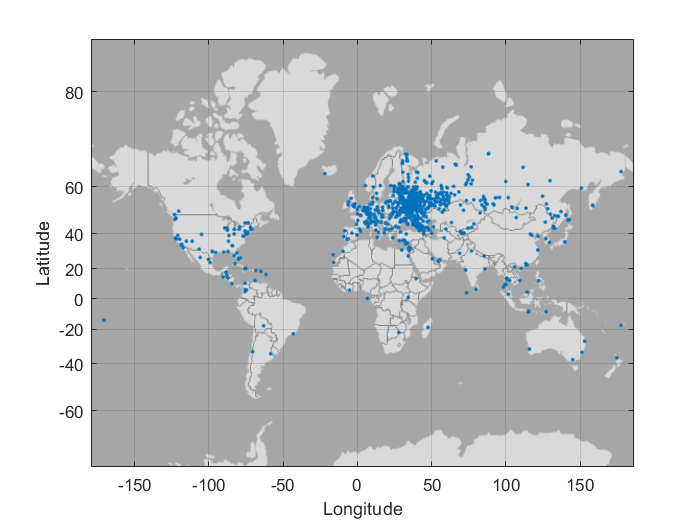

figure
geoscatter(C.lat, C.long, '.')

Отобразим топ 10 городов по количеству человек

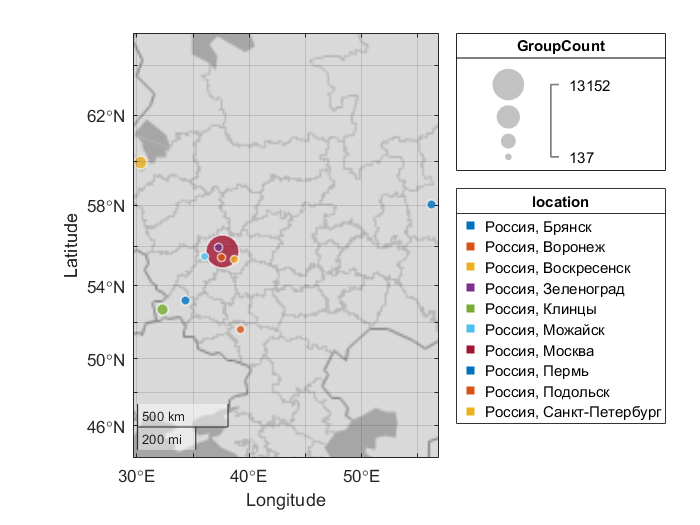

figure
C10 = topkrows(C, 10, 'GroupCount');
C10.location = categorical(C10.location);
geobubble(C10, 'lat', 'long', 'SizeVariable', 'GroupCount', 'ColorVariable', 'location');
legend

### Текстовый анализ статусов

(*Text Analytics Toolbox*)

Некоторые пользователи ставят в соцсети текстовые статусы.

Объединим их в один текст

s = string(data.status);
s = join(s);

Предобработаем текст

s = lower(s);
s = strrep(s, 'ё', 'е');
s = erasePunctuation(s);

Токенизируем текст и проведем обработку

doc = tokenizedDocument(s);
doc = removeLongWords(doc, 15);
doc = removeShortWords(doc, 2);
doc = removeWords(doc, ["чтобы"]);

Составляем из токенов "мешок" фраз по 3 слова

bn = bagOfNgrams(doc, 'NgramLengths', 3);

Визуализируем "облако слов"

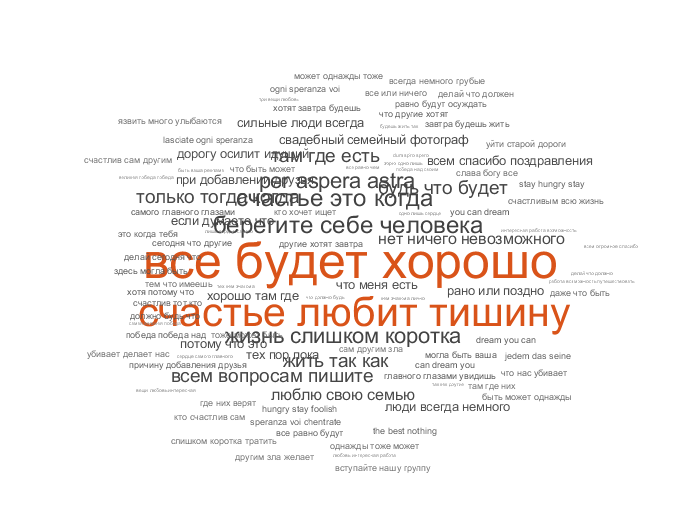

figure
wc = wordcloud(bn);

*Pavel Roslovets, *[*ETMC Exponenta*](https://exponenta.ru/)* © 2018*